%% ========== Setup ========== %%
% ===== Setup
clc; clear; close all;

% ===== Initial Value
ub = [10, 10];
lb = [-10, -10];
x0 = [0, 0];

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    6.000000e+00    0.000e+00    3.961e+00
    1       6    5.519416e+00    0.000e+00    3.882e+00    4.902e+00
    2       9   -2.499657e-01    0.000e+00    8.595e-03    2.396e+00
    3      12   -2.499970e-01    0.000e+00    2.775e-03    6.606e-03
    4      15   -2.499988e-01    0.000e+00    2.129e-03    2.703e-03
    5      18   -2.500000e-01    0.000e+00    1.250e-04    1.079e-03
    6      21   -2.500000e-01    0.000e+00    2.500e-05    1.078e-05
    7      24   -2.500000e-01    0.000e+00    2.500e-07    5.735e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

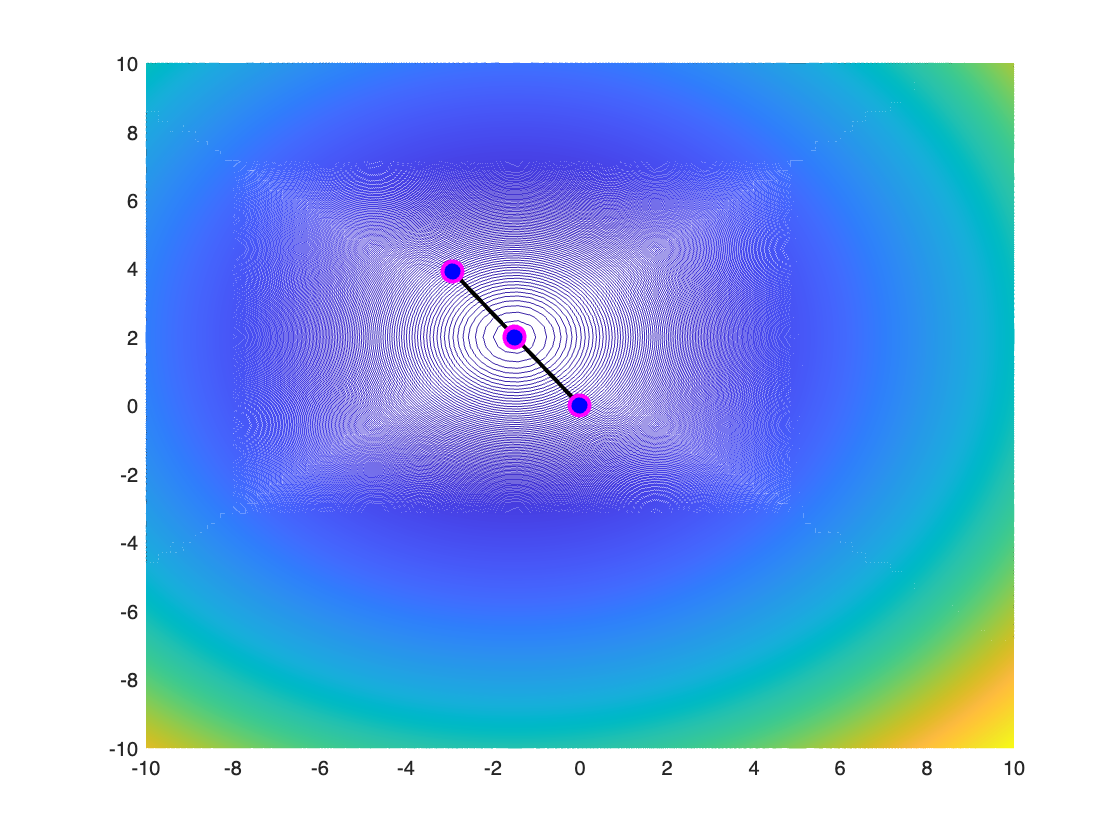

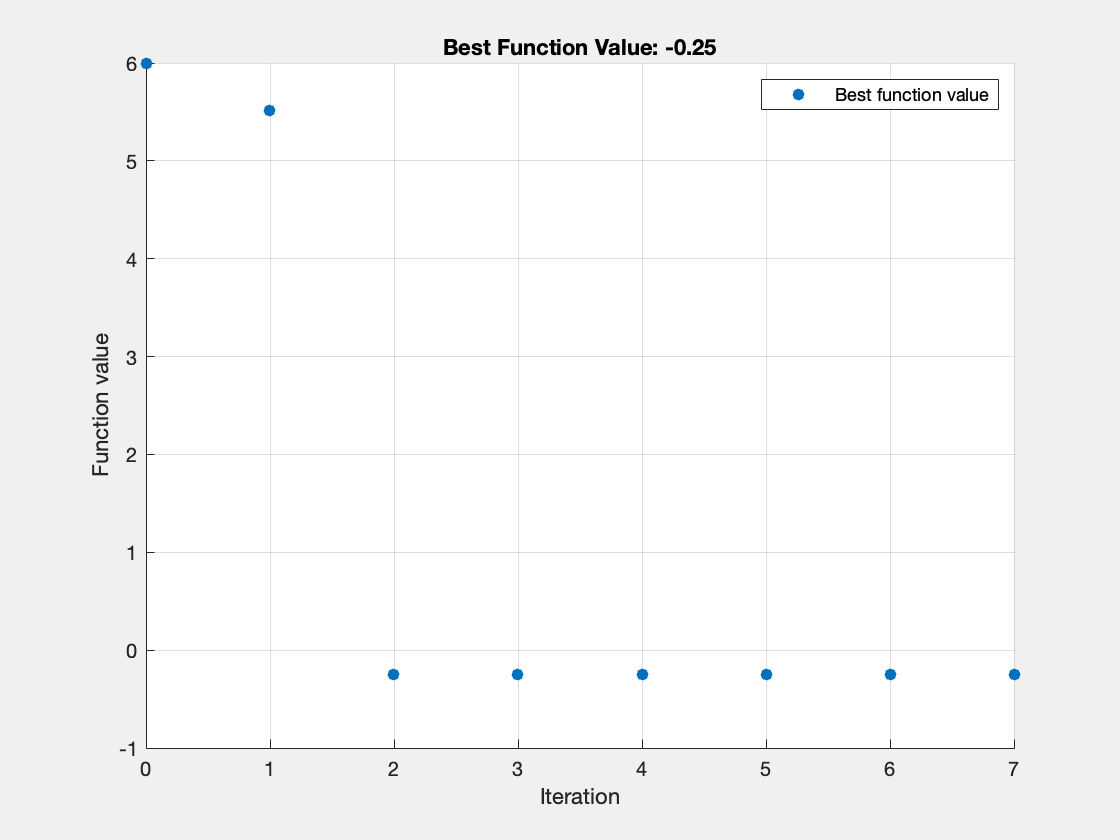

% Set nondefault solver options
options = optimoptions("fmincon","OutputFcn",@plotUpdate1,"Display","iter",...
    "PlotFcn","optimplotfvalconstr");

% Solve
[solution,objectiveValue] = fmincon(@objectiveFcn,x0,[],[],[],[],lb,ub,[],...
    options);


% Clear variables
clearvars options
function f = objectiveFcn(optimInput)
% Example:
% Minimize Rosenbrock's function
% f = 100*(y - x^2)^2 + (1 - x)^2

% Edit the lines below with your calculation
x = optimInput(1);
y = optimInput(2);
f = x^2 + y^2 + 3*x - 4*y + 6;
end
